# Matrices de Rotación Básicas

A continuacion encuentra un ejemplo que ilustra la aplicacion de las matrices de rotacion basicas sobre sistemas de referencia en 3D.

Se inicia con un valor de angulo en radianes (-pi,pi). Los ejes iniciales antes de rotar se repesentan por vectores columna dentro de una matriz

ang = -1.02159;
axes_o = [1 0 0;0 1 0;0 0 1]; %ejes iniciales

A continuación se aplica a rotación en torno a cada eje de forma independiente. Las lineas punteadas representan lo ejes antes de rotar y las lineas continuas los ejes después de haber sido rotados.

## Rotacion sobre eje X

%Aplicando la rotacion en torno al eje X
R_x = [1 0 0; ...
        0 cos(ang) -sin(ang); ...
        0 sin(ang) cos(ang)]

R_x =     1.0000         0         0
         0    0.5220    0.8529
         0   -0.8529    0.5220


axes_fx = R_x * axes_o

axes_fx =     1.0000         0         0
         0    0.5220    0.8529
         0   -0.8529    0.5220


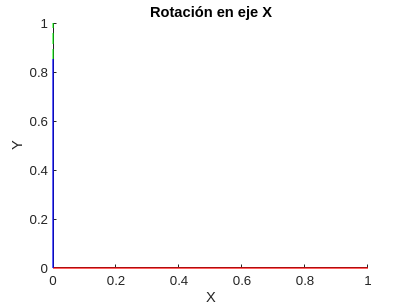

%grafica
figure(1)
title('Rotación en eje X')
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
%Ejes fijos
plot3([0 1],[0 0],[0 0],'--r','LineWidth',0.5)
plot3([0 0],[0 1],[0 0],'--g','LineWidth',0.5)
plot3([0 0],[0 0],[0 1],'--b','LineWidth',0.5)

%Ejes rotados
plot3([0 axes_fx(1,1)],[0 axes_fx(2,1)],[0 axes_fx(3,1)],'-r','LineWidth',1)
plot3([0 axes_fx(1,2)],[0 axes_fx(2,2)],[0 axes_fx(3,2)],'-g','LineWidth',1)
plot3([0 axes_fx(1,3)],[0 axes_fx(2,3)],[0 axes_fx(3,3)],'-b','LineWidth',1)
hold off

## Rotacion sobre eje Y

%Aplicando la rotacion en torno al eje Y
R_y = [cos(ang) 0 sin(ang); ...
        0 1 0; ...
        -sin(ang) 0 cos(ang)]

R_y =     0.5220         0   -0.8529
         0    1.0000         0
    0.8529         0    0.5220


axes_fy = R_y * axes_o

axes_fy =     0.5220         0   -0.8529
         0    1.0000         0
    0.8529         0    0.5220


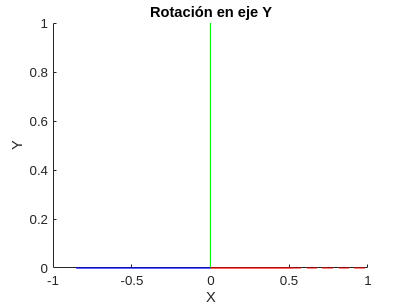

%grafica

figure(2)
title('Rotación en eje Y')
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
%Ejes fijos
plot3([0 1],[0 0],[0 0],'--r','LineWidth',0.5)
plot3([0 0],[0 1],[0 0],'--g','LineWidth',0.5)
plot3([0 0],[0 0],[0 1],'--b','LineWidth',0.5)

%Ejes rotados
plot3([0 axes_fy(1,1)],[0 axes_fy(2,1)],[0 axes_fy(3,1)],'-r','LineWidth',1)
plot3([0 axes_fy(1,2)],[0 axes_fy(2,2)],[0 axes_fy(3,2)],'-g','LineWidth',1)
plot3([0 axes_fy(1,3)],[0 axes_fy(2,3)],[0 axes_fy(3,3)],'-b','LineWidth',1)
hold off

## Rotacion sobre eje Z

%Aplicando la rotacion en torno al eje Z
R_z = [cos(ang) -sin(ang) 0; ...
       sin(ang) cos(ang) 0;
       0 0 1]

R_z =     0.5220    0.8529         0
   -0.8529    0.5220         0
         0         0    1.0000


axes_fz = R_z * axes_o

axes_fz =     0.5220    0.8529         0
   -0.8529    0.5220         0
         0         0    1.0000


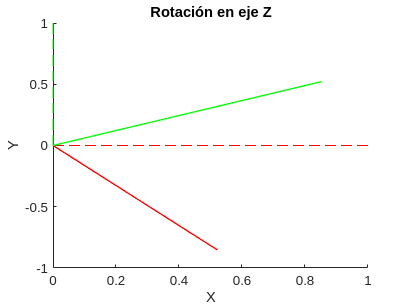

%grafica

figure(3)
title('Rotación en eje Z')
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
%Ejes fijos
plot3([0 1],[0 0],[0 0],'--r','LineWidth',0.5)
plot3([0 0],[0 1],[0 0],'--g','LineWidth',0.5)
plot3([0 0],[0 0],[0 1],'--b','LineWidth',0.5)

%Ejes rotados
plot3([0 axes_fz(1,1)],[0 axes_fz(2,1)],[0 axes_fz(3,1)],'-r','LineWidth',1)
plot3([0 axes_fz(1,2)],[0 axes_fz(2,2)],[0 axes_fz(3,2)],'-g','LineWidth',1)
plot3([0 axes_fz(1,3)],[0 axes_fz(2,3)],[0 axes_fz(3,3)],'-b','LineWidth',1)
hold off